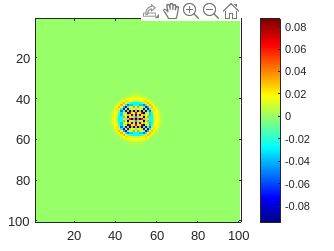

Index exceeds the number of array elements. Index must not exceed 100.

c = 1500;           % speed of sound in water (m/s)
SIZE = 100;         % size of each array
dt = 0.0001;        % temporal step size
dx = 1;             % spatial step size
rho = 997;          % density of water in kg/m^3
Sc = (c * dt) / dx; % courant number
Pr = zeros(SIZE);   % pressure matrix
vx = zeros(SIZE);   % x-velocity matrix
vy = zeros(SIZE);   % y-velocity matrix

% source parameters
fc = 10;            % cutoff frequency (Hz)
n0 = 30;            % initial delay (samples)
sigma = sqrt(2 * log(2)) / (2 * pi * (fc / dt)); % flow resistivity

% create source function
n = 0:SIZE-1;
srcFn = exp(-dt^2 * (n-n0).^2 / (2*sigma^2));
srcFn = filter([1 -1], [1 -0.995], srcFn); % DC blocker

% visualization parameters
h = imagesc(Pr);
colormap('jet');
colorbar;
xlim([1 SIZE]);
ylim([1 SIZE]);

% simulation loop
for count = 1:2000
    time = count * dt; % convert counter to time value
    
    % update x-velocity
    for mm = 1:SIZE-1
        vx(mm,:) = vx(mm,:) - (Sc / (c * rho)) * (Pr(mm+1,:) - Pr(mm,:));
    end
    
    % update y-velocity
    for nn = 1:SIZE-1
        vy(:,nn) = vy(:,nn) - (Sc / (c * rho)) * (Pr(:,nn+1) - Pr(:,nn));
    end
    
    % update pressure
    for mm = 2:SIZE
        for nn = 2:SIZE
            Pr(mm,nn) = Pr(mm,nn) - (c * rho * Sc) * (vx(mm,nn) - vx(mm-1,nn) + vy(mm,nn) - vy(mm,nn-1));
        end
    end
    
    % add source function
    Pr(SIZE/2, SIZE/2) = Pr(SIZE/2, SIZE/2) + srcFn(count);
    
    % update visualization
    set(h, 'CData', Pr);

xlim([1 101])
ylim([1 101])
    drawnow;
end